# Examine Dual-List Session using Temporal Field Bayes - Item Difference Trial Period Event Aligned

fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE11_Session146'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
    {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];
% fileDirs = [{'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE13_Session103'},...
%     {'D:\WorkBigDataFiles\PFC\Dual List Sessions\GE17_Session110'}];

numChancePerms = 10;

postCLim = [0 0.05];

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);

## Compile DL TIP data

tic;
for ani = 1:length(fileDirs)
    %% Create & setup initial object and data variables (if initial file)
    mlb = MLB_SM(fileDirs{ani});
    % Create Analysis Variables
    if ani == 1 
        % Real Posteriors
        realPDF = cell(length(mlb.odrVect), 2, length(fileDirs));
        realOdr = cell(length(mlb.odrVect), 2, length(fileDirs));
        % Chance Posteriors
        chancePDF = cell(length(mlb.odrVect), 2);
        chanceOdr = cell(length(mlb.odrVect), 2);
        chanceList = cell(length(mlb.odrVect), 2);
    end
    mlb.binSize = 200;
    mlb.dsRate = 50;
    mlb.windows = {[-500 500]};
    mlb.bayesType = 1;

    %% Process Port Entry Aligned Observations
    mlb.alignments = {'PokeIn'};
    mlb.SetLikes_ISC;
    mlb.Process_LikelyL1O;
    realPDF(:,1,ani) = mlb.post;
    realOdr(:,1,ani) = cellfun(@(a){mlb.TabulateBayesPost(a,mlb.decodeIDvects(:,4))}, mlb.post);
    %% Process Port Withdrawal Aligned Observations
    mlb.alignments = {'PokeOut'};
    mlb.SetLikes_ISC;
    mlb.Process_LikelyL1O;
    realPDF(:,2,ani) = mlb.post;
    realOdr(:,2,ani) = cellfun(@(a){mlb.TabulateBayesPost(a,mlb.decodeIDvects(:,4))}, mlb.post);
end

Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed
Compiling StatMatrix Data....Completed


toc

Elapsed time is 31.759873 seconds.


## Compile Trial Data Across Rats

prePeriodLog = mlb.obsvTimeVect<0;
postPeriodLog = mlb.obsvTimeVect>0;

posDiff = cell(length(mlb.odrVect),4);
posID = cell(length(mlb.odrVect),1);
odrID = cell(length(mlb.odrVect),1);
listID = cell(length(mlb.odrVect),1);
for odr = 1:length(mlb.odrVect)
    % Identify the current position based on the odor ID
    curPos = mod(mlb.odrVect(odr),10);
    % Use that to identify which other odor also belongs in that position
    posOdrs = mlb.odrSeqs(:,curPos);
    % Break out the data to analyze into temporary variables
    temp_PIdata = cell2mat(realOdr(odr,1,:));
    temp_POdata = cell2mat(realOdr(odr,2,:));
    % Identify which pages in the array are just used for padding & remove them
    nanLog = squeeze(isnan(temp_PIdata(1,1,:)));
    temp_PIdata(:,:,nanLog) = [];
    temp_POdata(:,:,nanLog) = [];
    % Calculate the difference between decodings of the two position matched odors
    temp_PIdiff = squeeze(diff(temp_PIdata(:,ismember(mlb.odrVect,posOdrs),:),1,2)*-1);
    temp_POdiff = squeeze(diff(temp_POdata(:,ismember(mlb.odrVect,posOdrs),:),1,2)*-1);
    % Calculate trial period specific averages
    posDiff{odr,1} = mean(temp_PIdiff(prePeriodLog,:),1)';
    posDiff{odr,2} = mean(temp_PIdiff(postPeriodLog,:),1)';
    posDiff{odr,3} = mean(temp_POdiff(prePeriodLog,:),1)';
    posDiff{odr,4} = mean(temp_POdiff(prePeriodLog,:),1)';
    % Create ID vectors to be used with the anova
    posID{odr} = ones(size(temp_PIdiff,2),1)*curPos;
    odrID{odr} = ones(size(temp_PIdiff,2),1)*odr;
    listID{odr} = ones(size(temp_PIdiff,2),1)*(mlb.odrVect(odr)<10);
end

posDiff = cell2mat(posDiff);
posID = cell2mat(posID);
odrID = cell2mat(odrID);
listID = cell2mat(listID);


## Calculate Repeated Measures ANOVAs

timeStrs = arrayfun(@(a){sprintf('TP%i',a)}, 1:4);
tpMeas = table((1:4)', 'VariableNames', {'Time_Periods'});
rmTable = table('Size', [size(posDiff,1), 7],...
    'VariableTypes', [{'categorical'}, {'categorical'}, {'categorical'}, repmat({'double'}, [1,4])],...
    'VariableNames', [{'Position'}, {'Odor'}, {'List'}, timeStrs]);
rmTable.Position = categorical(posID);
rmTable.Odor = categorical(odrID);
rmTable.List = categorical(listID);
rmTable(:,4:end) = array2table(posDiff);
listRM = fitrm(rmTable, sprintf('%s-%s~List', timeStrs{1}, timeStrs{end}), 'WithinDesign', tpMeas);
listRtable = ranova(listRM)

listRtable = 3×8 table
                                 SumSq       DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                ________    ____    ________    _______    __________    __________    __________    __________

    (Intercept):Time_Periods    0.048677       3    0.016226    0.48729       0.69113       0.58523       0.58564       0.48537
    List:Time_Periods             3.2878       3      1.0959     32.913    8.6979e-21    6.0466e-13    5.7335e-13    1.4321e-08
    Error(Time_Periods)           70.225    2109    0.033298                                                                   


odrRM = fitrm(rmTable, sprintf('%s-%s~Position+List', timeStrs{1}, timeStrs{end}), 'WithinDesign', tpMeas);
odrRtable = ranova(odrRM)

odrRtable = 4×8 table
                                 SumSq       DF      MeanSq        F         pValue       pValueGG      pValueHF      pValueLB 
                                ________    ____    ________    _______    __________    __________    __________    __________

    (Intercept):Time_Periods    0.055745       3    0.018582    0.56418       0.63866       0.54353        0.5439       0.45283
    Position:Time_Periods         1.0594       9     0.11771     3.5739     0.0002012     0.0029052     0.0028815      0.013791
    List:Time_Periods              3.417       3       1.139     34.582    8.2093e-22    1.3568e-13    1.2814e-13    6.3284e-09
    Er

wtList = posDiff(listID==1,:);
nvList = posDiff(listID==0,:)

nvList =     0.1347    0.0423   -0.0133   -0.0133
    0.4697   -0.2388   -0.8777   -0.8777
    0.1267   -0.4488   -0.8986   -0.8986
    0.0476   -0.0492   -0.7250   -0.7250
    0.0829   -0.3021   -0.1271   -0.1271
    0.1168    0.0151   -0.8093   -0.8093
   -0.0567   -0.1931   -0.4047   -0.4047
    0.3032    0.0917   -0.3369   -0.3369
    0.0375   -0.0897    0.3418    0.3418
   -0.0740   -0.2229   -0.5639   -0.5639


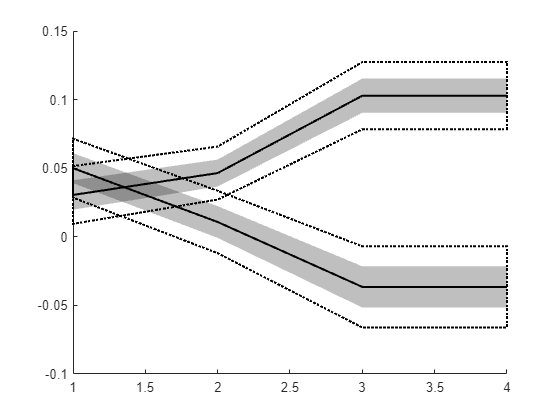

figure;
p(1) = mlb.PlotMeanVarLine(1:4, wtList,1,0.05,'k');
p(1) = mlb.PlotMeanVarLine(1:4, nvList,1,0.05,'k');

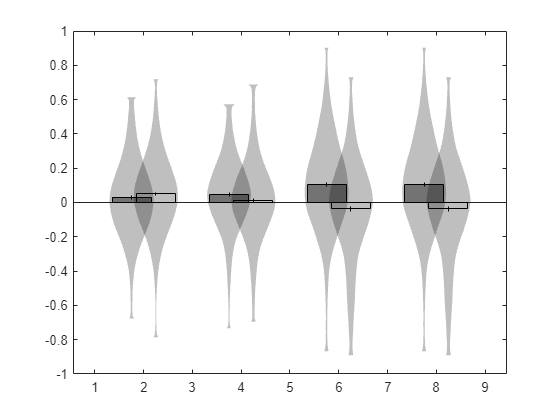

figure;
for t = 1:4
    mlb.PlotMeanVarViolin(t*2-0.25,wtList(:,t),1,0.05,'k', 'filled');
    hold on;
    mlb.PlotMeanVarViolin(t*2+0.25,nvList(:,t),1,0.05,'k');
end